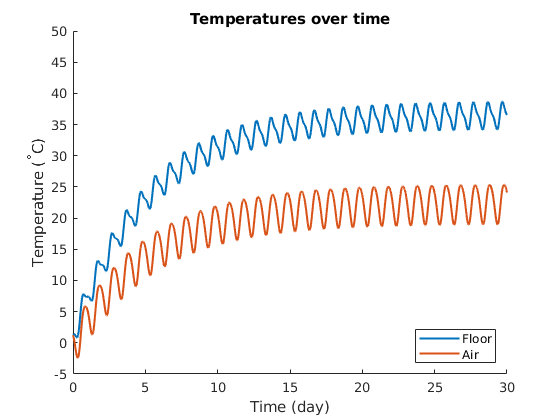

day_0 = 0;
tspan_days = 30;
resolution = 5000;

tspan = linspace(day_0, tspan_days, resolution) * 24 * 3600;

insulation_thickness = 0.01;
tile_thickness = 1;

[t_out, Y_out] = ode_solver(insulation_thickness, tile_thickness, tspan);
figure();
hold on
plot(t_out/(3600 * 24), Y_out, 'linewidth', 1.5)
title("Temperatures over time")
xlabel("Time (day)")
ylabel("Temperature (^\circC)")
legend("Floor", "Air", 'location', 'southeast')

ylim([-5, 50])

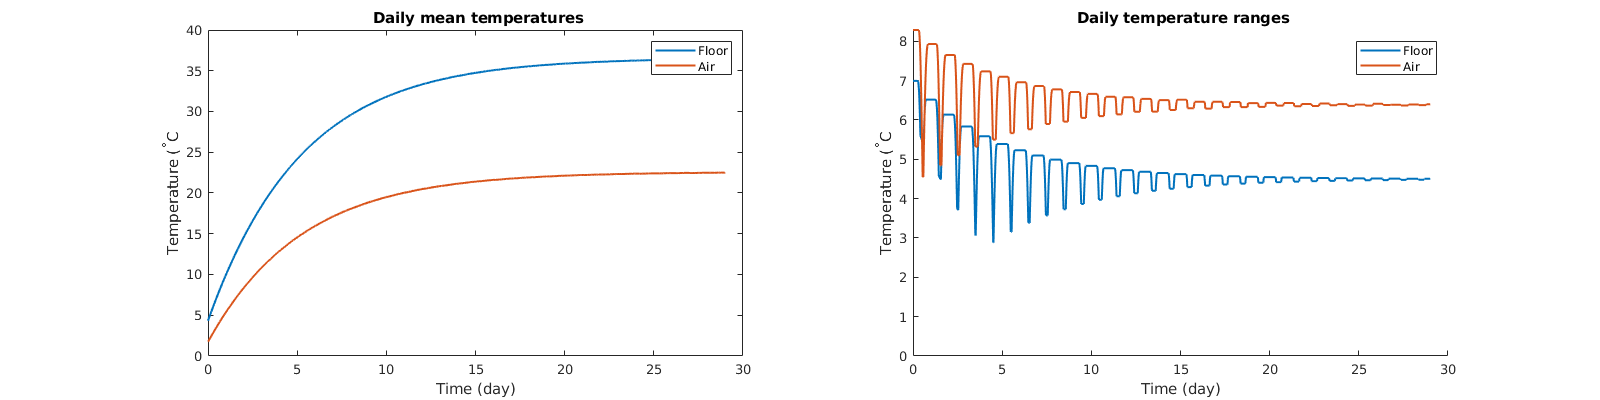

samples_per_second = resolution / (tspan(end) - tspan(1));
samples_per_day = samples_per_second * 24 * 3600;

% Moving mean temperature per day
movmean_temps = movmean(Y_out, samples_per_day, 1, 'Endpoints', "discard");

% Moving max temperature per day
movmax_temps = movmax(Y_out, samples_per_day, 1, 'Endpoints', "discard");
movmin_temps = movmin(Y_out, samples_per_day, 1, 'Endpoints', "discard");
range_temps = movmax_temps - movmin_temps;

size_movmean = size(movmean_temps, 1);

fig_mean = figure();
set(fig_mean, 'position', [0, 0, 1600, 400])
subplot(1, 2, 1)
plot(t_out(1:size_movmean) / 24 / 3600, movmean_temps, 'linewidth', 1.5)
xlabel("Time (day)")
ylabel("Temperature (^\circC")
title(" Daily mean temperatures")
legend("Floor", "Air")

subplot(1, 2, 2)
hold on
plot(t_out(1:size_movmean) / 24 / 3600, range_temps, 'linewidth', 1.5)
ylim([0, max(range_temps, [], 'all')])
xlabel("Time (day)")
ylabel("Temperature (^\circC")
title(" Daily temperature ranges")
legend("Floor", "Air")

v_errors = trapz(t_out(1:size_movmean) / 24 / 3600, movmean_temps - 25, 1)

v_errors =   167.5887 -178.9639


insulation_thickness_range = [0.001,0.1];
tile_thickness_range = [0.3, 5];
vector_from_range = @(range, samples) linspace(range(1), range(2), samples);

grid_dim = 10;
v_insulation_thickness = vector_from_range(insulation_thickness_range, grid_dim);
v_tile_thickness = vector_from_range(tile_thickness_range, grid_dim);

% Create a matrix where each row is a unique insulation/tile thickness pair
% ie. consolidate all points in the 2d grid into one list

[mat_insulation, mat_tile] = meshgrid(v_insulation_thickness, v_tile_thickness);
mat_pairings = [mat_insulation(:), mat_tile(:)];

samples_per_second = resolution / (tspan(end) - tspan(1));
samples_per_day = samples_per_second * 24 * 3600;

mat_costs = zeros(size(mat_pairings));

tic
for i = 1 : size(mat_pairings, 1)
    [~, Y_out_i] = ode_solver(mat_pairings(i, 1), mat_pairings(i, 2), tspan);
    
    % Moving mean temperature per day
    movmean_temps = movmean(Y_out_i, samples_per_day, 1, 'Endpoints', "discard");
    
    % Moving max temperature per day
    movmax_temps = movmax(Y_out_i, samples_per_day, 1, 'Endpoints', "discard");
    movmin_temps = movmin(Y_out_i, samples_per_day, 1, 'Endpoints', "discard");
    range_temps = movmax_temps - movmin_temps;
    
    size_movmean = size(movmean_temps, 1);
    
    % Integrate mean temperature error (distance from ideal temp) over time
    error_temps = movmean_temps - 25;
    v_cumerrors = trapz(t_out(1:size_movmean) / 24 / 3600, sqrt(error_temps.^2), 1);
    
    % Integrate temperature oscillations over time
    v_cumrange= trapz(t_out(1:size_movmean) / 24 / 3600, range_temps, 1);
    
    % Cost function: Total error + total range
    % This way we attempt to minimize both the deviation from 25deg C, as
    % well as the temperature oscillation over time.
    v_costs = v_cumerrors + v_cumrange;
    mat_costs(i, :) = v_costs(:)';
end
toc

Elapsed time is 5.671550 seconds.


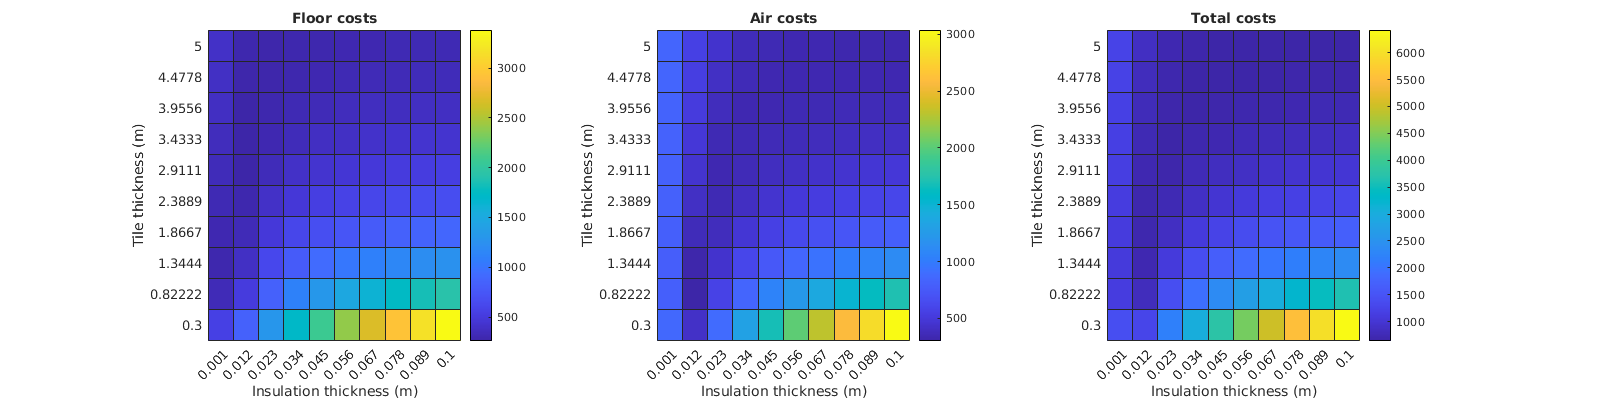

fig_heatmaps = figure();
set(fig_heatmaps, 'Position', [0, 0, 1600, 400])

subplot(1, 3, 1)
hmap_floor = heatmap(v_insulation_thickness, v_tile_thickness, reshape(mat_costs(:, 1), size(mat_insulation)));
hmap_floor.YDisplayData = flip(v_tile_thickness);
xlabel("Insulation thickness (m)")
ylabel("Tile thickness (m)")
title("Floor costs")
colormap default;
colormap([1 0 0; colormap()]);

subplot(1, 3, 2)
hmap_air = heatmap(v_insulation_thickness, v_tile_thickness, reshape(mat_costs(:, 2), size(mat_insulation)));
hmap_air.YDisplayData = flip(v_tile_thickness);
xlabel("Insulation thickness (m)")
ylabel("Tile thickness (m)")
title("Air costs")
colormap default;
colormap([1 0 0; colormap()]);


subplot(1, 3, 3)
v_cost_all = sum(mat_costs, 2);
hmap_all = heatmap(v_insulation_thickness, v_tile_thickness, reshape(v_cost_all, size(mat_insulation)));
hmap_all.YDisplayData = flip(v_tile_thickness);
xlabel("Insulation thickness (m)")
ylabel("Tile thickness (m)")
title("Total costs")
colormap default;

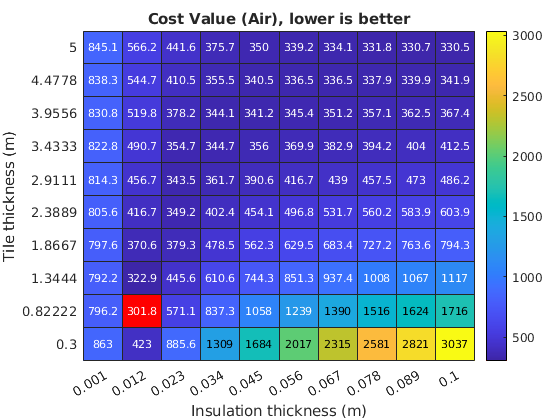

figure()
hmap_air_only = heatmap(v_insulation_thickness, v_tile_thickness, reshape(mat_costs(:, 2), size(mat_insulation)));
hmap_air_only.YDisplayData = flip(v_tile_thickness);
xlabel("Insulation thickness (m)")
ylabel("Tile thickness (m)")
title("Cost Value (Air), lower is better, red is lower")
colormap default;
colormap([1 0 0; colormap()]);

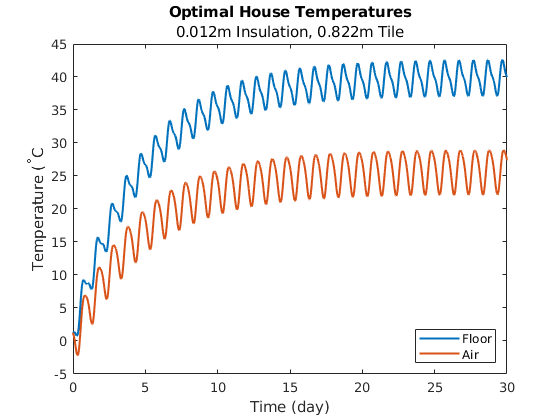

% Find parameters that minimize air cost
optimal_for_air = mat_pairings(mat_costs(:, 2) == min(mat_costs(:, 2)), :);

% Simulate the specific house
[~, Y_out_optimal] = ode_solver(optimal_for_air(1), optimal_for_air(2), tspan);
figure()
plot(tspan / 24 / 3600, Y_out_optimal, 'linewidth', 1.5)
xlabel("Time (day)")
ylabel("Temperature (^\circC")
title("Optimal House Temperatures", "0.012m Insulation, 0.822m Tile")
legend("Floor", "Air", 'location', 'southeast')